Uploading Data:

% mydata=importStormData("StormEvents_2014.csv")

View the table.

table(mydata.Year,mydata.Month,mydata.Event_Type)

ans = 59465×3 table
    Var1      Var2            Var3       
    ____    ________    _________________

    2014    February    Heavy Snow       
    2014    February    Heavy Snow       
    2014    January     Heavy Snow       
    2014    November    Heavy Snow       
    2014    February    Heavy Snow       
    2014    April       Strong Wind      
    2014    January     Heavy Snow       
    2014    April       Strong Wind      
    2014    March       Strong Wind      
    2014    November    Strong Wind      
    2014    July        Thunderstorm Wind
    2014    July        Thunderstorm Wind
    2014    July        Thunderstorm Wind
    2014    July        Thunderstorm Wind
    2014    July        Thunderstorm Wind
    2014    July        Thunderstorm Wind


mydata.Year=categorical(mydata.Year)

mydata = 59465×25 table
    EpisodeID     Event_ID         State        Year     Month         Event_Type          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                               

summary

mydata.Crop_Cost(ismissing(mydata.Crop_Cost))=0;
mydata.Property_Cost(ismissing(mydata.Property_Cost))=0;
mydata.Total_Cost=mydata.Property_Cost+mydata.Crop_Cost;

groupsummary

groupsummary(mydata,'Month',{'mean','min','median','max'},'Total_Cost');
mydata(mydata.Total_Cost>0,:)

ans = 13528×25 table
    EpisodeID     Event_ID         State        Year     Month      Event_Type       Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                        

New question

groupsummary(mydata(mydata.Total_Cost>0,:),'Year',{'mean','min','median','max'},'Total_Cost')

ans = 1×6 table
    Year    GroupCount    mean_Total_Cost    min_Total_Cost    median_Total_Cost    max_Total_Cost
    ____    __________    _______________    ______________    _________________    ______________

    2014      13528         5.6882e+05             10                5000              1.5e+09    


New lesson

cost=groupsummary(mydata,'Month','sum','Total_Cost')

cost = 12×3 table
      Month      GroupCount    sum_Total_Cost
    _________    __________    ______________

    April           5244          1.302e+09  
    August          4259         2.2795e+09  
    December        2712         1.5639e+09  
    February        6028         3.8749e+07  
    January         7577          2.505e+07  
    July            6606          5.567e+08  
    June            9446          1.015e+09  
    March           4169         1.1633e+08  
    May             5296         3.8743e+08  
    November        2790          4.356e+07  
    October         2402         6.9673e+07  
    September       2936         2.9712e+08  


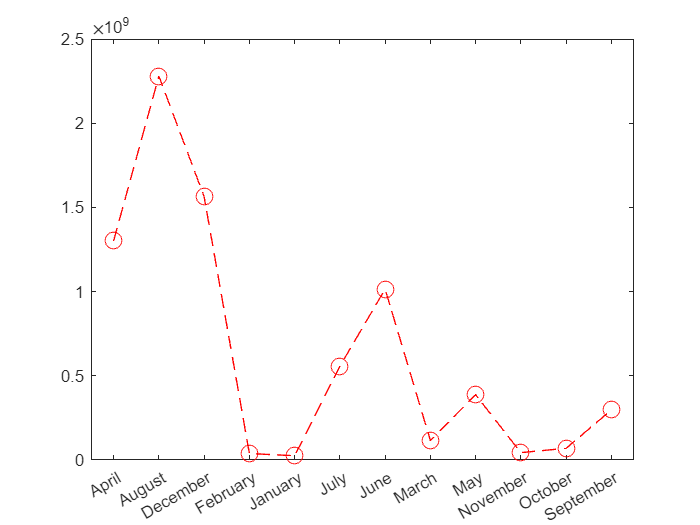

plot(cost.Month,cost{:,end},"Color","red","LineStyle","--","Marker","o","MarkerSize",10)

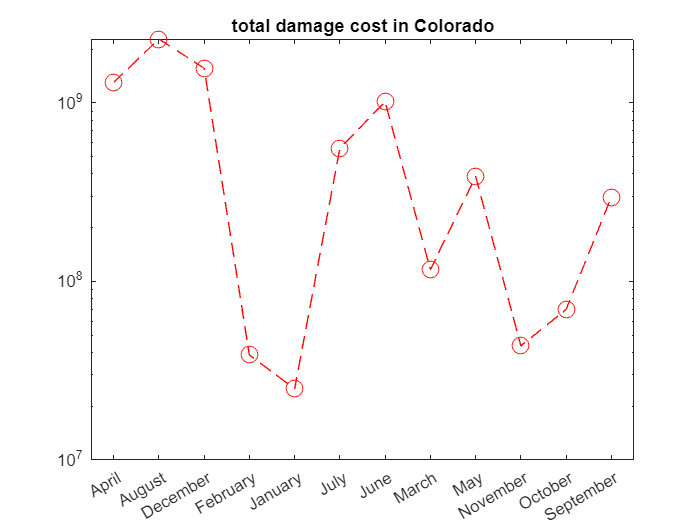

semilogy(cost.Month,cost{:,end},"Color","red","LineStyle","--","Marker","o","MarkerSize",10)
title('total damage cost in Colorado')

%If we click on the plot we can change the settings.

New plots

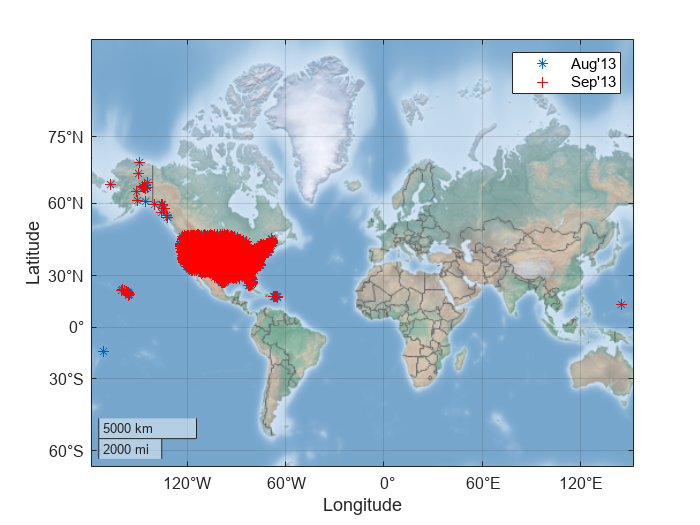

geoplot(mydata.Begin_Lat,mydata.Begin_Lon,'*')
hold on
% savefig('deneme.fig')
geoplot(mydata.Begin_Lat,mydata.Begin_Lon,"Color","red","LineStyle","none","Marker","+")
legend({'Aug''13','Sep''13'})
% Because of I dont have the data I need the show it on the another data.
geobasemap('colorterrain')